# Signal CA2 

#### Aryan Soltani Mohammadi   810198558 

1) 

    It is just kind of an approach for checking similarities that may be in diffrent times.

2)

    row1, col1 size of the first matrice and row2, col2 is for the second one.

    Corr(k, l) = sigma from i = 1 to i = row(sigma (j = 1 to j = col)    mat1(i, j) * mat2(i - k, j- l))

    when i - k or j - l becomes negative we consider it as -1

3) 

 first we calculate the correlation between our matrice with any other matrice in dataset then one which its             maximum  value is maximum could be the matrice answer because by some shifting the simiarity become higher.

close all
clear
clc
plateArrC = openPlate();

Picture also has been shown after each operation in pipeline.

plateArrM = rgb2Bw(plateArrC);

tresh_need = 90.3020

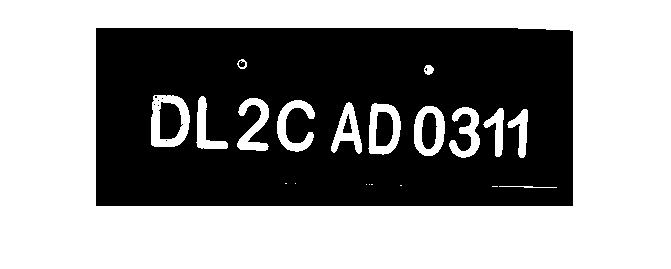

figure
imshow(plateArrM)

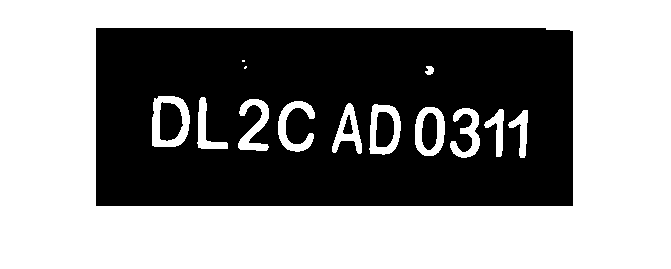

[row, col] = size(plateArrM);
imgClean = CleanBw(plateArrM, [0, 10000, 500, fix(col / 300), fix(col/200)]);
figure
imshow(imgClean)

[L, Ne] = bwlabel(imgClean);

mapSet = loadmap("./Map Set");

license_answer = []


license_answer =

     []



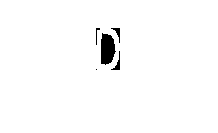

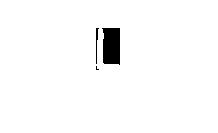

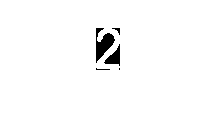

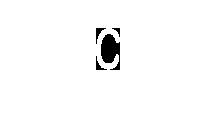

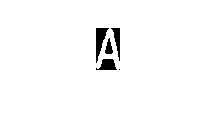

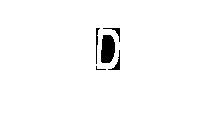

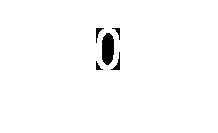

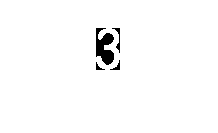

for iPatch = 1: Ne
    [r, c] = find(L == iPatch);
    best_answer = 0;
    patchCrop = imgClean(min(r):max(r), min(c):max(c));
    patchCrop = imresize(patchCrop, [42,24]);
    tresh_need = multithresh(patchCrop, 1); 
    [row, col] = size(patchCrop);
    for i = 1:row 
        for j = 1:col
            if patchCrop(i, j) > tresh_need 
                patchCrop(i, j) = 1;
            else 
                patchCrop(i, j) = 0;
            end
        end
    end
    rho = mapCorr(patchCrop, mapSet);
    [num] = size(rho, 1) ;
    [row, col] = size(patchCrop);
    name_map = '1';
    ans = -1;
    for j = 1:num
       if(rho{j, 2} > ans)
           ans = rho{j, 2};
           name_map = rho{j, 1};
       end
    end
    if(ans > 0.45)
        figure
        imshow(patchCrop);
        license_answer = [license_answer, name_map];
    end
end

disp(license_answer);

DL2CADo311


function [rho] = mapCorr(map1, mapSet)
    len = size(mapSet, 1);
    [row, col] = size(map1);
    rho = cell(len, 2);
    for i=1:len
        avg = 0;
        mat_now = mapSet{i, 2};
        cor_now = corr2(mat_now, map1);
        rho{i, 1} = mapSet{i, 1};
        rho{i, 2} = cor_now;
    end
end

This function loads all the pictures through the mapSet, which is a cell that each index has a path 

function [mapSet] = loadmap(mapDir)
    picture_dir = dir(mapDir);
    mapSet = cell(size(picture_dir, 1) - 2,2);
    for i = 3: size(picture_dir, 1)
        name_now = picture_dir(i).name(1);
        mapSet{i - 2, 1} = name_now;
        path = strcat(mapDir, '/');
        path = strcat(path, picture_dir(i).name);
        mat_now = imread(path);
        mapSet{i - 2, 2} = mat_now;
    end
end

This function is used for cleaning the noise pathes from picture first it find some rows that should be black by checking cleaningParams. Then by using eroding and dilation(type disk) method it eliminate small patches from the picture.

function [imgClean] = CleanBw(imgNoisy, cleaningParams)
    imgClean = imgNoisy;
    [row, col] = size(imgNoisy);
    for i = 1:row
        cnt_count = 0;
        last_seen = -1;
        flag = 0;
        cnt_now = 0;
        for j = 1:col
           if imgNoisy(i, j) ~= last_seen
               cnt_count = cnt_count + 1;
               last_seen = imgNoisy(i, j);
               cnt_now = 0;
           end
           cnt_now = cnt_now + 1;
           if(cnt_now > cleaningParams(3))
               flag = 1;
           end
        end
        if(cnt_count < cleaningParams(1)) || (cnt_count > cleaningParams(2)) || (flag == 1)
            for j = 1:col
                imgClean(i, j) = 0;
            end
        end
    end
    se = strel('disk', cleaningParams(4));
    imgClean = imerode(imgClean, se);
    se = strel('square', cleaningParams(5));
    imgClean = imdilate(imgClean, se);
end

This function takes the image, and convert it to a binary matrix with otso method.

function [imgBw] = rgb2Bw(imgColored)
    [row, col, temp] = size(imgColored);
    imgBw = zeros(row, col);
    for i = 1:row 
        for j = 1:col
           imgBw(i, j) = 0.299 * imgColored(i, j, 1) +  imgColored(i, j, 2) * 0.587 + imgColored(i, j, 2) * 0.114;
        end
    end
    tresh_need = multithresh(imgBw, 1)
    for i = 1:row 
        for j = 1:col
            if imgBw(i, j) > tresh_need 
                imgBw(i, j) = 0;
            else 
                imgBw(i, j) = 1;
            end
        end
    end
end

This function request a path and a filename from the user, and imread function transform the given image file to 3-dimensional array, which represent RGB of this picture.

function [plateArrC] = openPlate()
    [file, path] = uigetfile('*.jpg');
    complete_path = strcat(path, file);
    plateArrC = imread(complete_path);
end